%%% Transmission

% Le script suivant permet de simuler une barre de transmission et de déterminer la flèche et l'écart angulaire sur une barre en torsion.
% De nombreuses ameliorations peuvent etre apportees par la suite.

% Ce script est utile pour voir l'influence des differents parametres sur
% L'écart angulaire
%% Hypotheses
    %On se place dans le pire cas
    %On suppose que les forces subit par le barre sous toute suivant l'axe
    %y

%%
% clear all
% close all


## Parametres

% Vehicule
g=9.81;
mvec=220;
rep=0.55% répartission masse av/ar

rep = 0.5500

Kred=0.2;
cmot=90000;%N.mm
s=2;
L=0.5 %longeur de la barre de transmission

L = 0.5000

l1=0; %distance entre pignon et le palier
l2=0; %distance entre
Fchaine=10; %tension de la chaîne en N
Froue=g*mvec*rep/2.%effort roue sur l'arbre

Froue = 593.5050


%matériaux
%acier 36 Ni Cr Mo 16; X 2 Cr Ni 19-11

rho=7800;%kg/m^3
Re=[100:50:1000]%[800,180]; %Mpa ou N/mm^2

Re =          100         150         200         250         300         350         400         450         500         550         600         650         700         750         800         850         900         950        1000


E=ones(1, length(Re))*205000;%[205000,205000];%Mpa ou N/mm^2
v=0.3;
G=E./(2*(1+v));%Mpa ou N/mm^2
Tauadm=0.5.*Re./s

Tauadm =    25.0000   37.5000   50.0000   62.5000   75.0000   87.5000  100.0000  112.5000  125.0000  137.5000  150.0000  162.5000  175.0000  187.5000  200.0000  212.5000  225.0000  237.5000  250.0000


## Torsion

Cred=cmot/Kred; %Couple au niveau de l'arbre
d=(16*Cred./(3.14.*Tauadm)).^(1/3)% diametre de l'arbre en mm

d =    45.0977   39.3965   35.7941   33.2283   31.2690   29.7029   28.4098   27.3160   26.3733   25.5486   24.8182   24.1648   23.5752   23.0392   22.5488   22.0977   21.6807   21.2935   20.9325


Alpha=32*Cred*L./(3.14.*G.*d.^(4))% écart angulaire rad

Alpha = 	1.0e+-3 *

    0.0070    0.0121    0.0177    0.0239    0.0304    0.0374    0.0446    0.0522    0.0601    0.0683    0.0767    0.0853    0.0941    0.1032    0.1125    0.1220    0.1316    0.1415    0.1515


Theta=180/3.14.*Alpha% degré

Theta =     0.0004    0.0007    0.0010    0.0014    0.0017    0.0021    0.0026    0.0030    0.0034    0.0039    0.0044    0.0049    0.0054    0.0059    0.0064    0.0070    0.0075    0.0081    0.0087


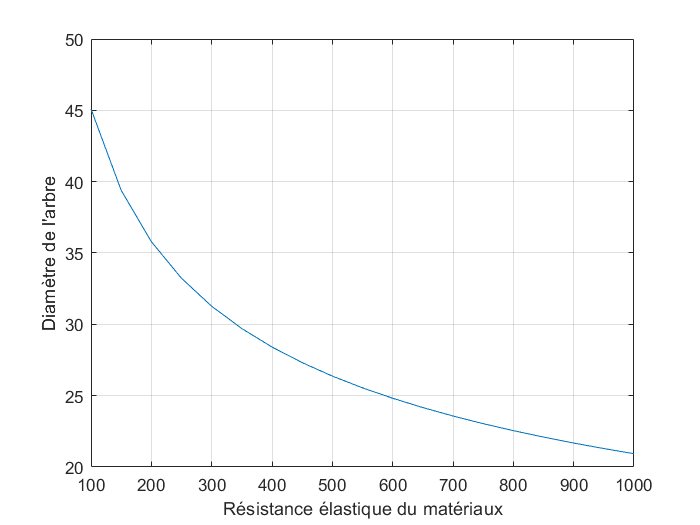

figure('Name','Choix diamètre de la transmission')
plot(Re,d)
grid()
xlabel('Résistance élastique du matériaux');
ylabel("Diamètre de l'arbre");

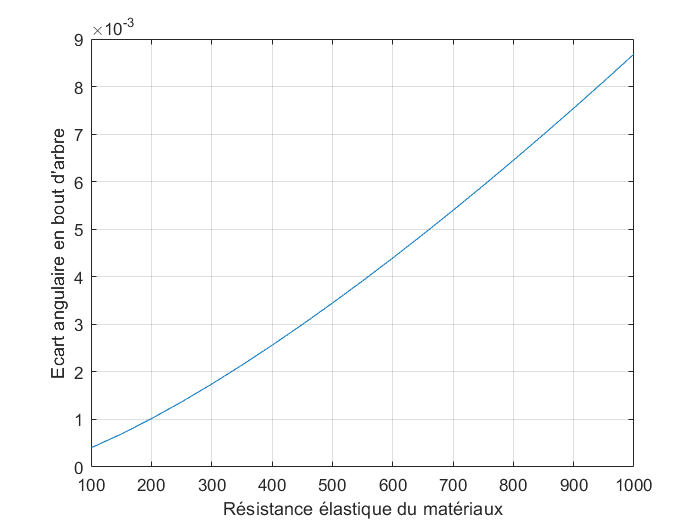


figure('Name',"Ecart angulaire en bout d'arbre")
plot(Re,Theta)
grid()
xlabel('Résistance élastique du matériaux');
ylabel("Ecart angulaire en bout d'arbre");

## Flexion

D=0.002

D = 0.0020

Igz=3.14*D^4/64;
L=0.15 %m

L = 0.1500

z=[0:L/100:L]

z =          0    0.0015    0.0030    0.0045    0.0060    0.0075    0.0090    0.0105    0.0120    0.0135    0.0150    0.0165    0.0180    0.0195    0.0210    0.0225    0.0240    0.0255    0.0270    0.0285    0.0300    0.0315    0.0330    0.0345    0.0360    0.0375    0.0390    0.0405    0.0420    0.0435    0.0450    0.0465    0.0480    0.0495    0.0510    0.0525    0.0540    0.0555    0.0570    0.0585    0.0600    0.0615    0.0630    0.0645    0.0660    0.0675    0.0690    0.0705    0.0720    0.0735


m=rho*3.14*D^2/4

m = 0.0245

Fchaine=100;% N
Froue=0;
Fb=Fchaine*l1/L+m*g/2-Froue*(1+l2/L)

Fb = 0.1201

Fa=m*g-Fchaine-Froue-Fb;
Mfz=zeros(1,length(z));
i=1;
Lp=0;
y=zeros(1,length(z))

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


C1=-(Fchaine+Fa)*L^2/8-Fchaine*l1*L/2

C1 = -3.3787e-04

C2=0

C2 = 0

C12=-(Fchaine+Fa)*(L/2)^2/2-Fchaine*l1*L/2+m*g*((L/2)^2/2-(L/2)*(L/2))

C12 = -0.0010

C22=C1*L/2+m*g*((L/2)^3/6-L^3/16)-C12*L/2

C22 = 1.6894e-05

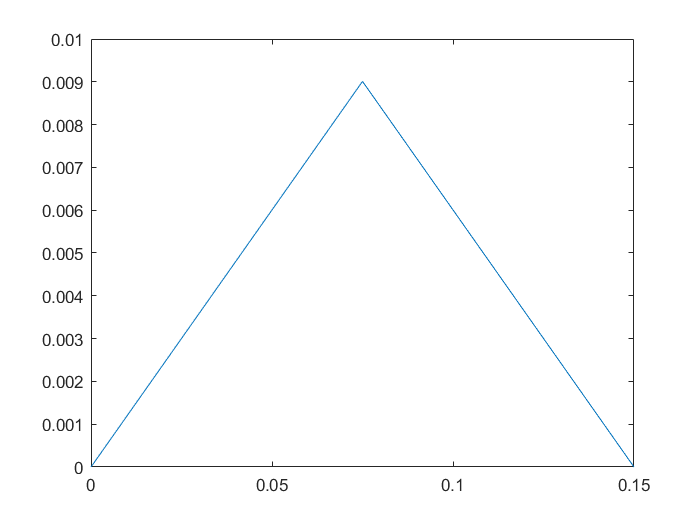

while Lp<L+l2+l1;
    if z(i)>0 & z(i)<=L/2;
        Mfz(i)=Fchaine*(z(i)+l1)+Fa*z(i);
        y(i)=Fchaine*(z(i)/6+l1/2)*z(i)^2+Fa*z(i)^3/6+C1*z(i);
    
    elseif z(i)>L/2;
        Mfz(i)=Fchaine*(z(i)+l1)+Fa*z(i)-m*g*(z(i)-L/2);
        y(i)=Fchaine*(z(i)/6+l1/2)*z(i)^2+Fa*z(i)^3/6-m*g*(L/4*z(i)^2-z(i)^3/6)+C12*z(i)+C22;
    end
    i=i+1;
    Lp=(i-1)*(L+l2+l1)/100;
end

%y=(1/(E(1)*Igz).*((Fchaine+Fa)/6).*z.^3+Fchaine*l1.*z.^2-Fchaine*l1*L/2.*z-(Fchaine+Fa)*L^2/6.*z)
plot(z,Mfz)

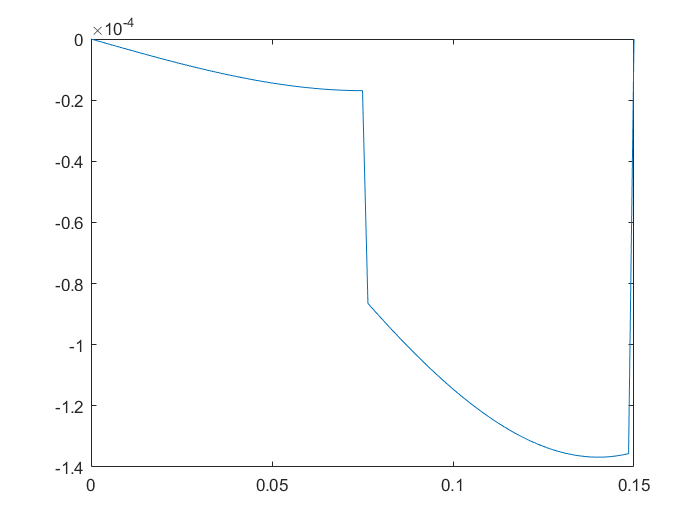

plot(z,y)